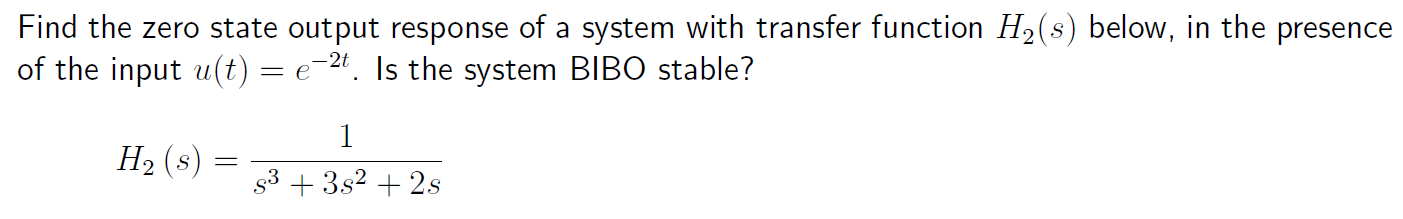

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.




H=1/(s^3+3*s^2+2*s)

H =
 
          1
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.



Y=zpk(minreal(H*(1/(s+2))))

Y =
 
         1
  ---------------
  s (s+2)^2 (s+1)
 
Continuous-time zero/pole/gain model.



pole(Y);
eig(Y);

[N,D]=tfdata(Y,'v');
[r,p]=residue(N,D)

r =     0.7500
    0.5000
   -1.0000
    0.2500


p =    -2.0000
   -2.0000
   -1.0000
         0


The system is NOT BIBO because one of the poles is 0.

## **RESIDUAL METHOD**

Y=zpk(minreal( H*1/s))
pole(Y)
eig(Y)

[N,D]=tfdata(Y,'v')
[r,p]=residue(N,D)





The system is BIBO because the real part of the poles is negative.

## **SYMBOLIC METHOD**

f(t)=exp(-2*t)
y=vpa(simplify(ilaplace(laplace(f)*H)),4)

h(t)=ilaplace(H)

x=simplify(1/(m*w)*int(f(tau)*h(t-tau),tau,[0 100000000]));
x=vpa(x,4)
fplot(x,t)
hold on
fplot(y,t)
hold off

% simulink;
% sim("ex2.slx");




The system is BIBO because the real part of the poles is negative.